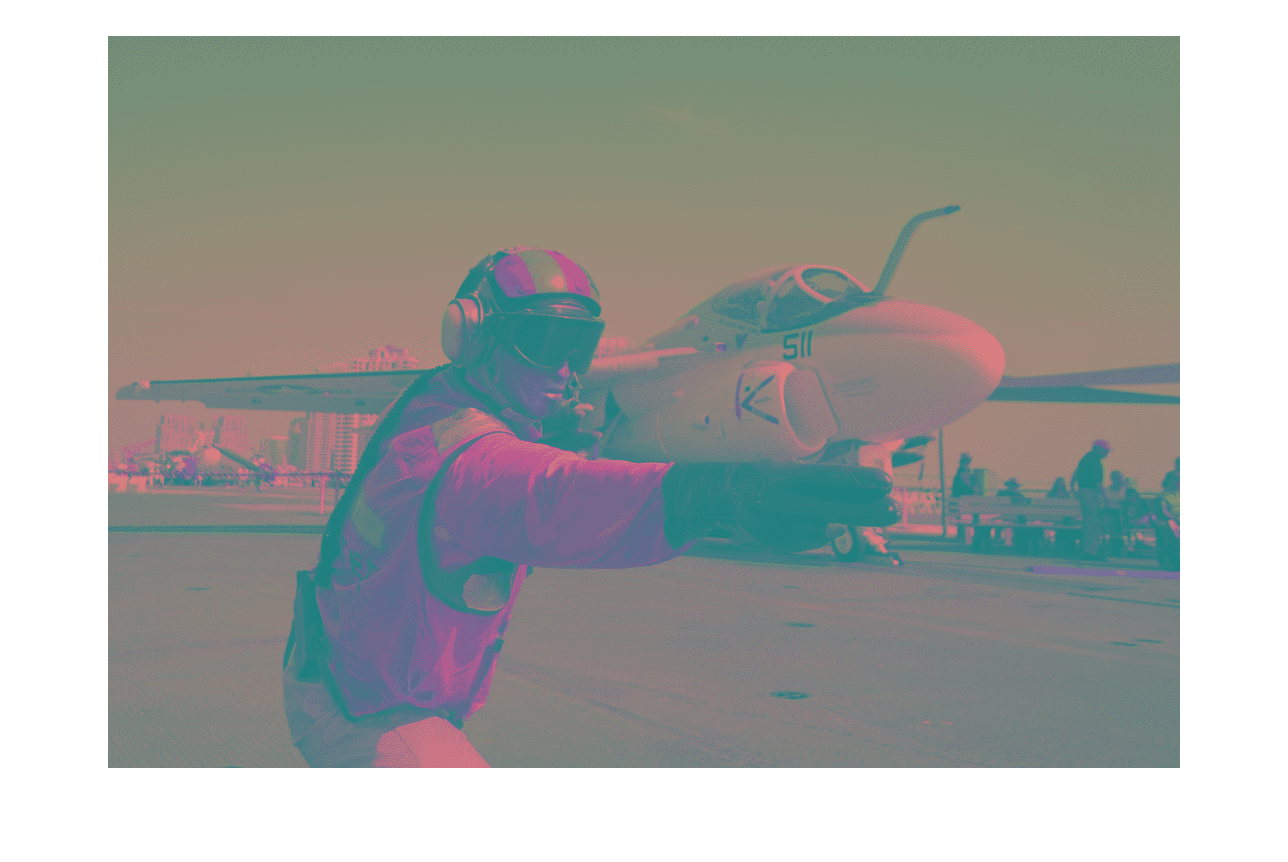

%convert the image to YUV type
[pilot] = imread('pilot.jpg');
pilot_YUV=jpgtoYUV(pilot);
imshow(pilot_YUV);

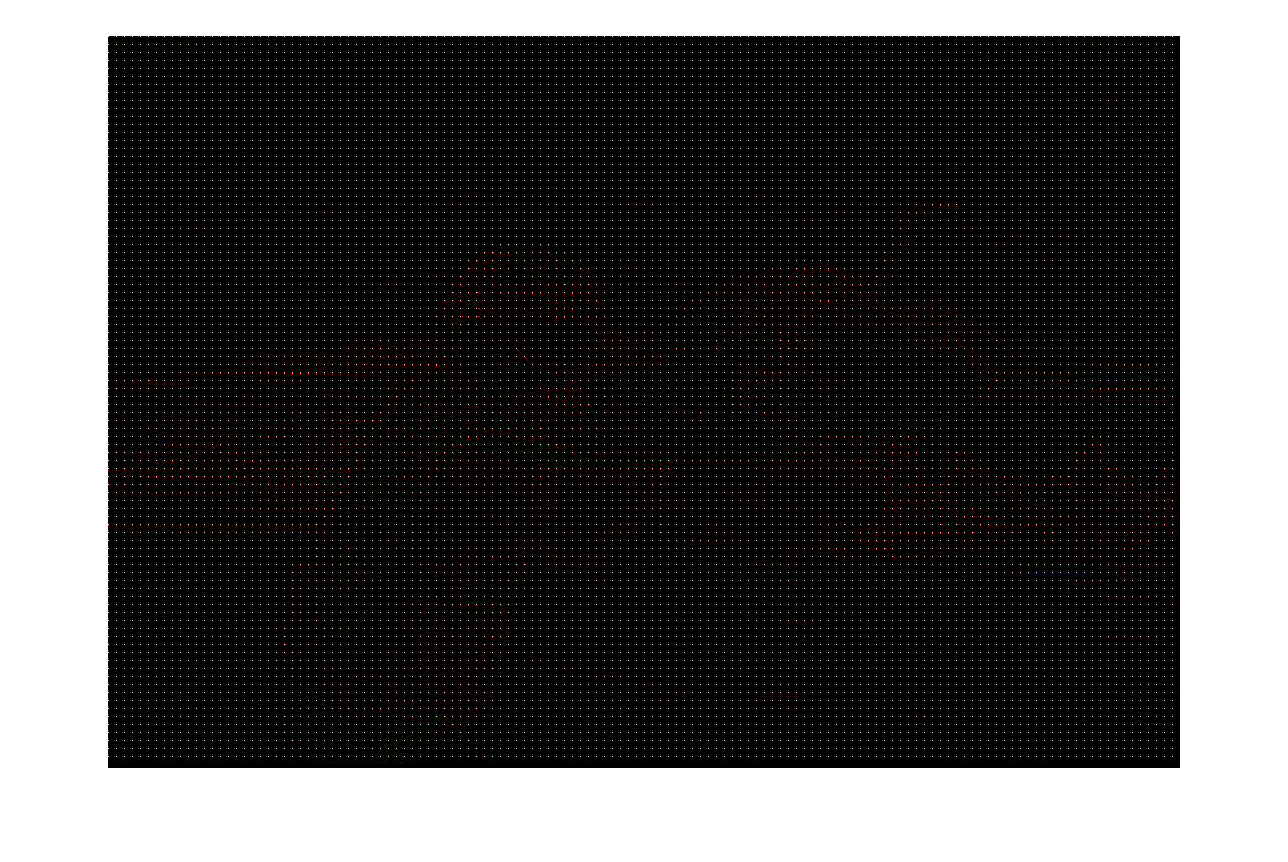


[row,col,channel]=size(pilot_YUV);
pilot_dct=zeros(row,col,channel);
pilot_YUV_recover=zeros(row,col,channel);
temp1=pilot_YUV(256:263,677:684,1);
for i=1:row/8
    for j=1:col/8
        for k=1:channel
            downsample_pilot=pilot_YUV(8*i-7:8*i,8*j-7:8*j,k);
            pilot_dct(8*i-7:8*i,8*j-7:8*j,k)=dct2(downsample_pilot);
        end
    end
end
imshow(pilot_dct);

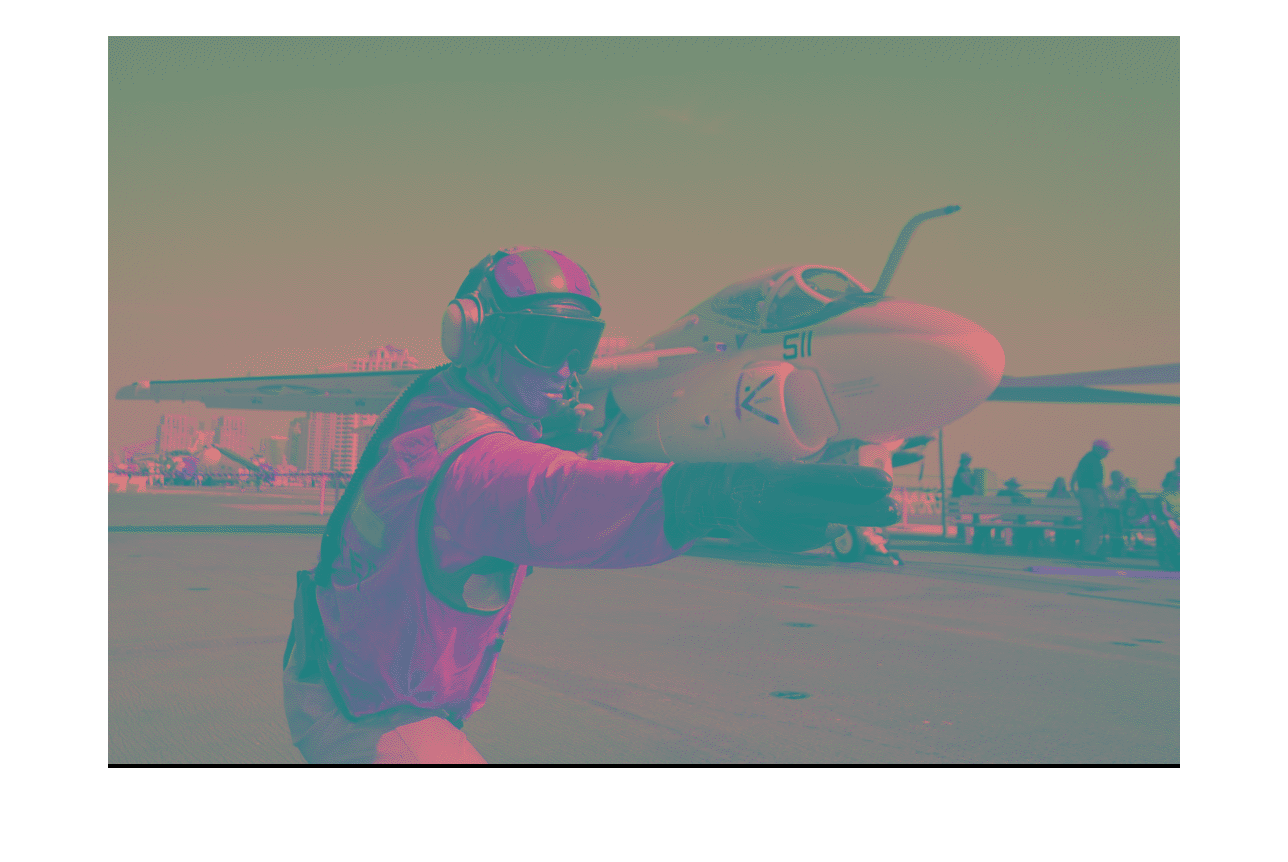

temp=pilot_dct(256:263,677:684,1);

for i=1:row/8
    for j=1:col/8
        for k=1:channel
            inverse_downsample_pilot=pilot_dct(8*i-7:8*i,8*j-7:8*j,k);
            pilot_YUV_recover(8*i-7:8*i,8*j-7:8*j,k)=idct2(inverse_downsample_pilot);
        end
    end
end
imshow(pilot_YUV_recover);